# Bifurcation diagram for a Berkolaiko-Marzuola-Pelinovsky quantum graph

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

## Construct the quantum graph and find the first few eigenfunctions

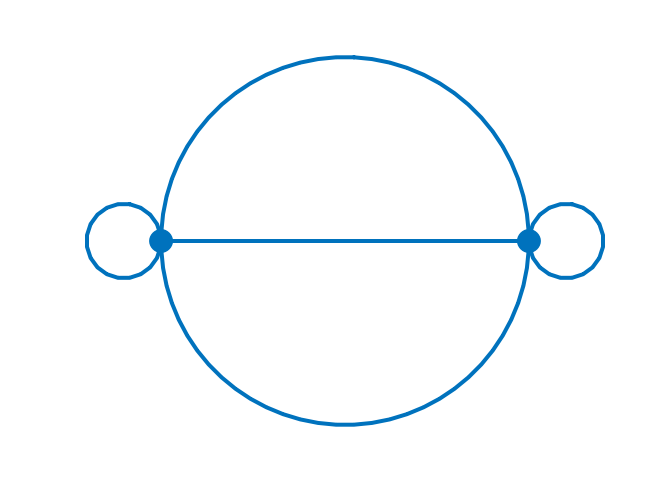

Created directory data/BMP/020.
Run number is 20.


tag='BMP';
Phi=quantumGraphFromTemplate(tag); % use the default values
dataDir = makeContinuationDirectory(Phi,tag);

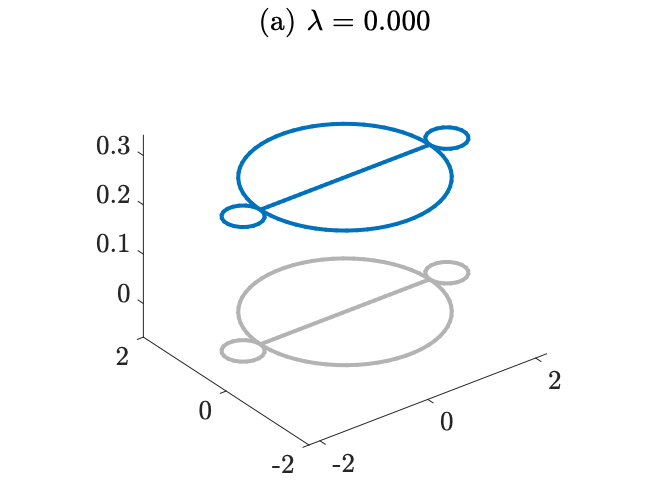

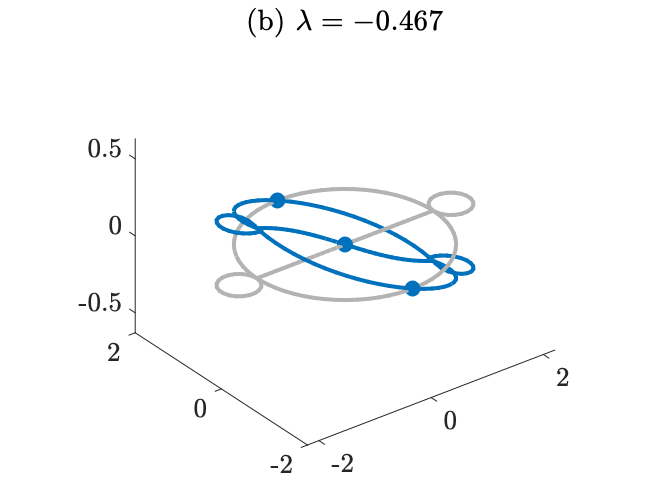

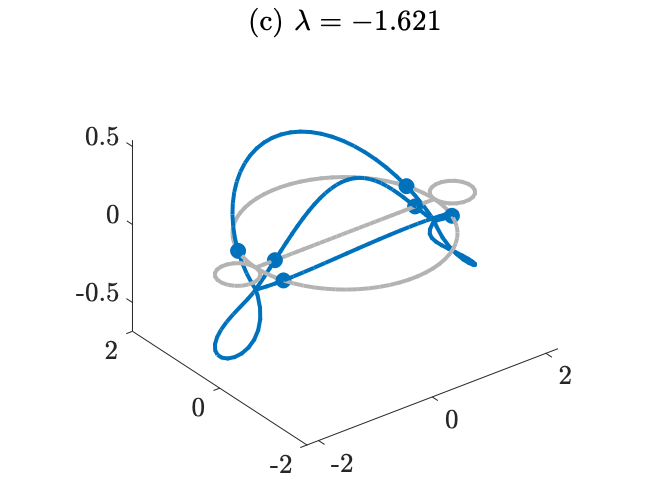

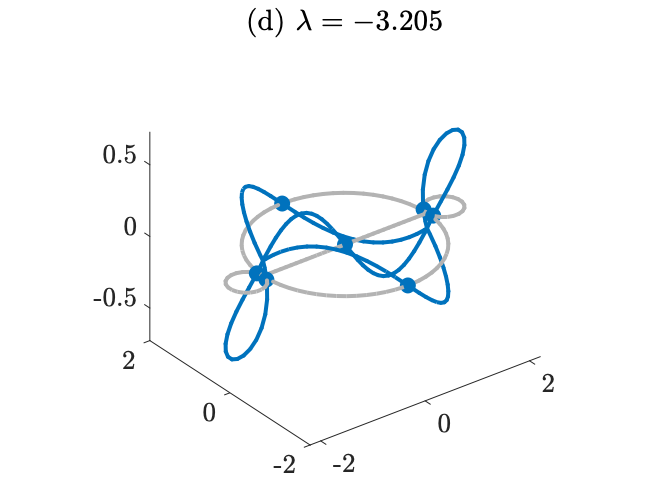

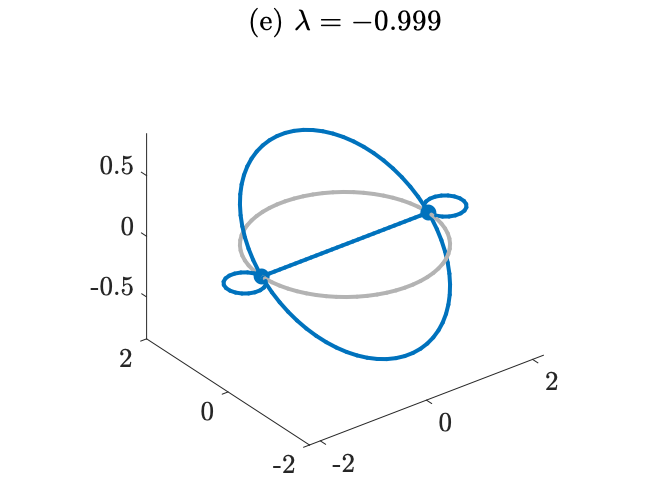

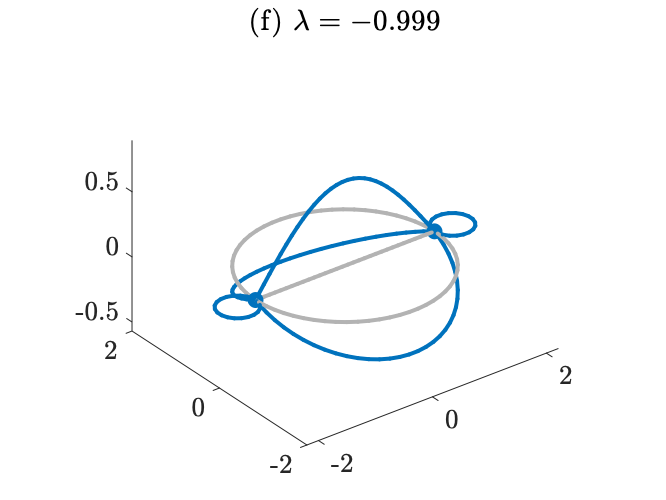

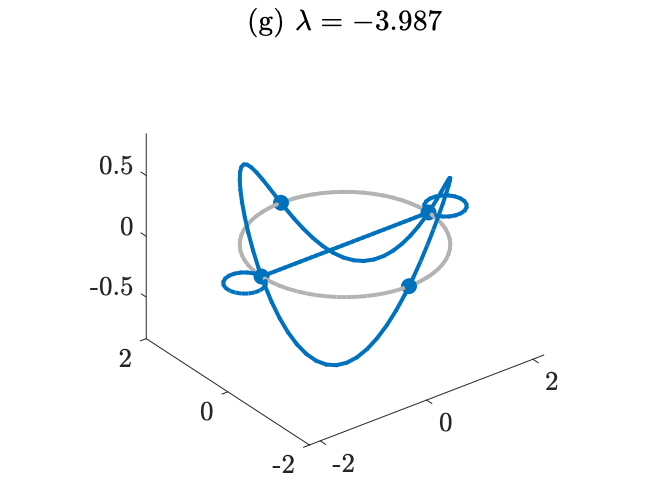

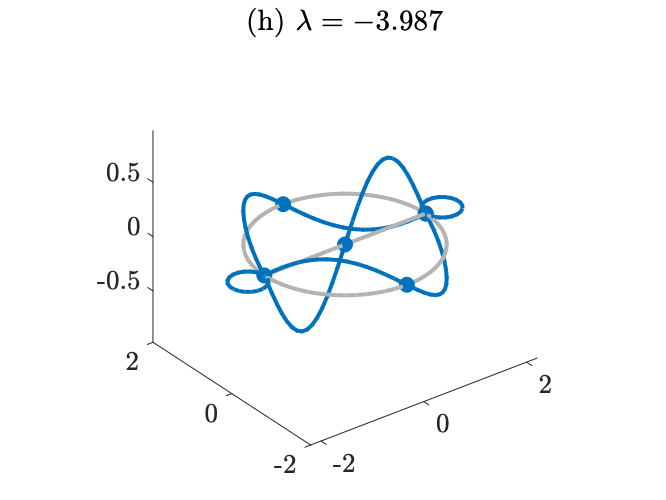

nToPlot=4;
nDoubles=2;
saveEigenfunctions(Phi,tag,dataDir,nToPlot,nDoubles);

fcns=saveNLSFunctionsGraph(dataDir,Phi); % use the default cubic nonlinearity

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-2,'NThresh',10,'plotFlag',false,'maxTheta',2,'minNormDelta',1e-3);
branch1=continueFromEig(dataDir,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data/BMP/020/branch001.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 14.


## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in branch at bifurcation location 1.

branch2=continueFromBranchPoint(dataDir,branch1,1,1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/BMP/020/branch002.
No branching bifurcations found.


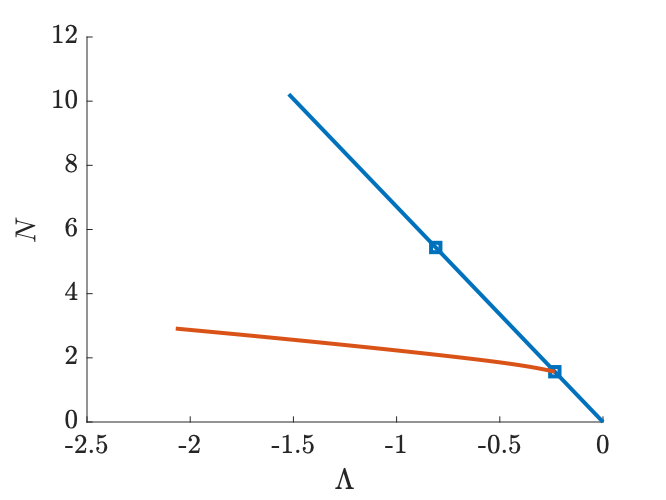

bifurcationDiagram(dataDir)

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a transcritical bfirucation, we need to continue in both directions, the branch stored in branch`1` at bifurcation location 2

branch3=continueFromBranchPoint(dataDir,branch1,2,1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data/BMP/020/branch003.
No branching bifurcations found.


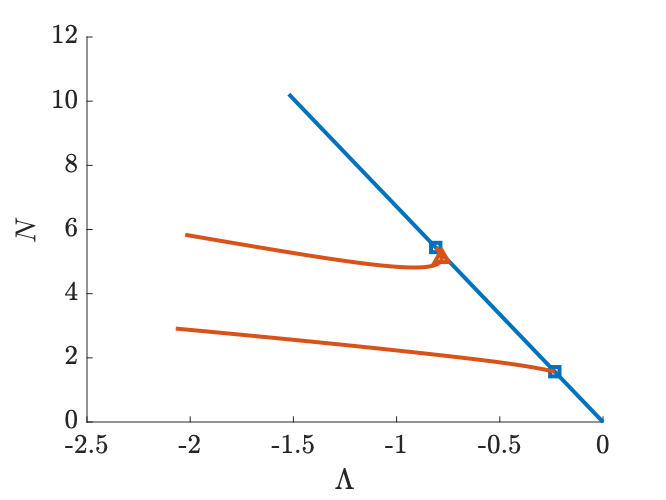

bifurcationDiagram(dataDir)

branch4=continueFromBranchPoint(dataDir,branch1,2,-1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/BMP/020/branch004.
No branching bifurcations found.


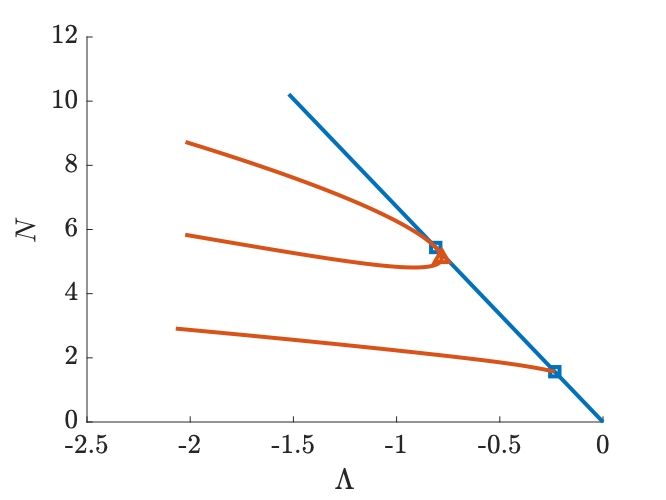

bifurcationDiagram(dataDir)

## Compute a large-amplitude solution, save it to a file, and compute its continuation

Lambda0 = -4;
edges = [1 2 5];
signs = [1 1 1];
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

File saved to data/BMP/020/savedFunction.001.
File number is 1. 


options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
[branch55]=continueFromSaved(dataDir,filenumber,-1,options);

N threshold crossed.
Branch number 5.
Data saved to directory data/BMP/020/branch005.
Branching Bifurcation at solution number 29.
Branching Bifurcation at solution number 74.
Branching Bifurcation at solution number 127.
Branching Bifurcation at solution number 149.


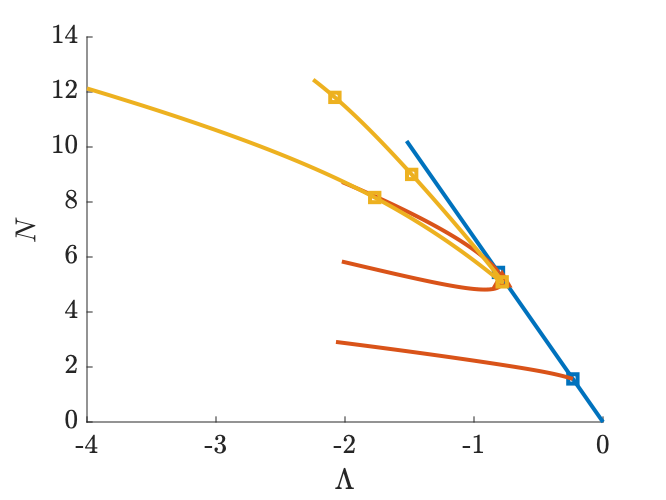

bifurcationDiagram(dataDir)

## Plot some solutions

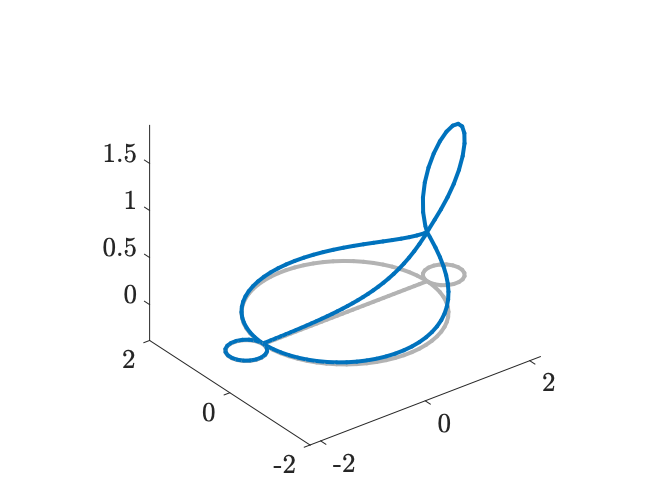

plotSolution(dataDir,branch2,'last')

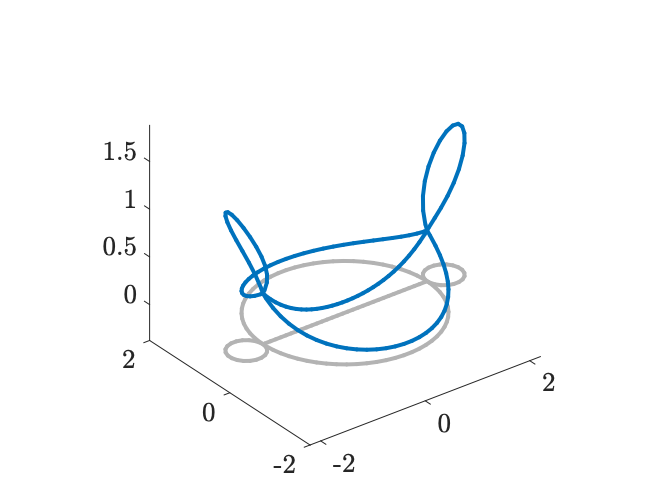

plotSolution(dataDir,branch3,'last')

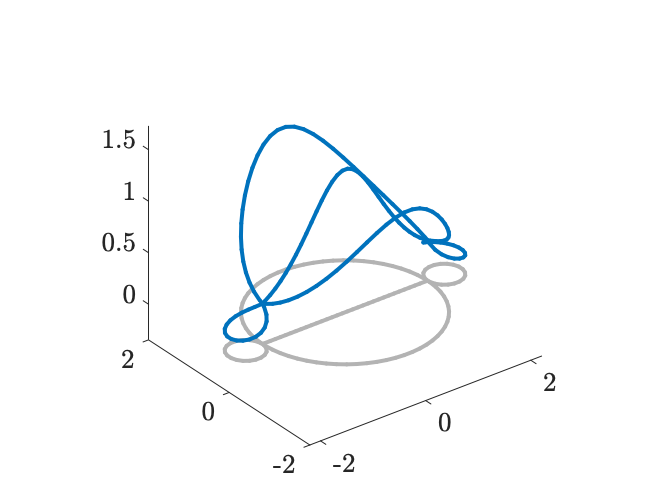

plotSolution(dataDir,branch4,'last')